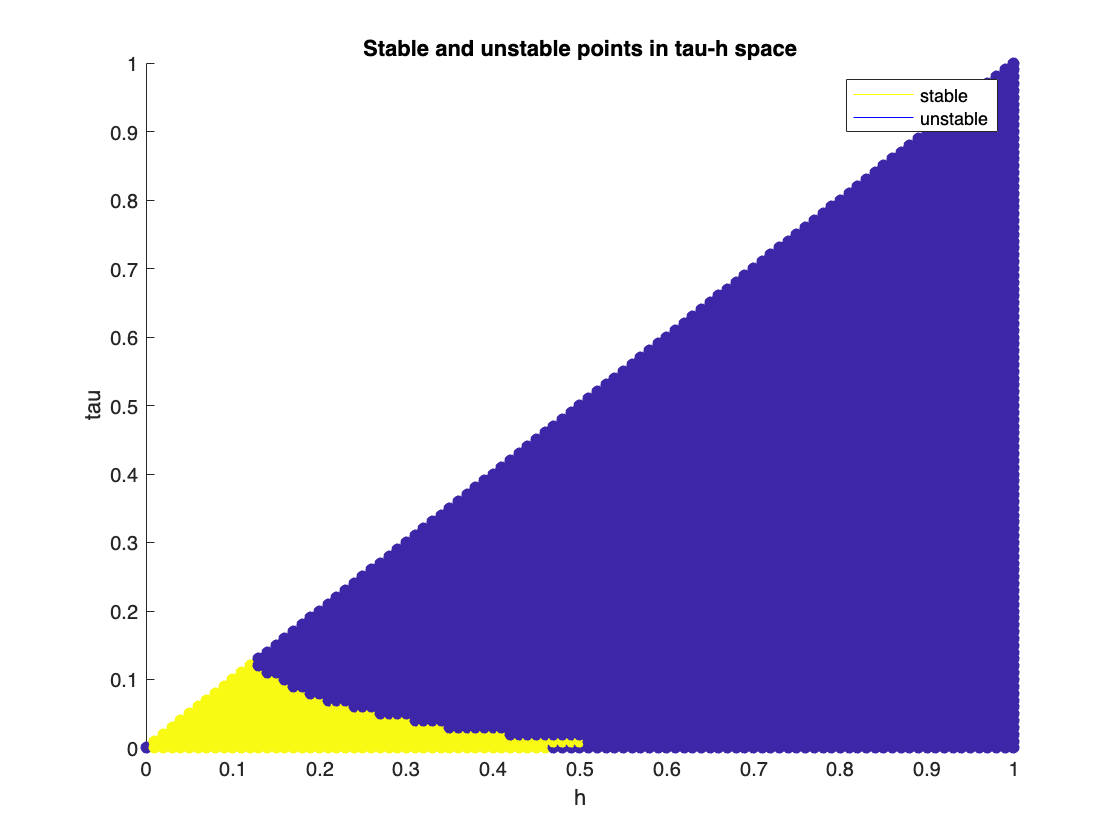

%Qeustion2
clc
clear 

a = 5;
b = 3;
c = 1;
A = [a-b, 0.5-c; 0, 1];
B = [0; 1];
p1 = [-1+2j, -1-2j];
K1 = place(A, B, p1);

% create grid of tau and h values
tau_values = 0:0.01:1;
h_values = 0:0.01:1;

% preallocate arrays for x, y, and color values
x = [];
y = [];
colors = [];

for i = 1:length(tau_values)
    h = h_values(i);
    tau_values_i = 0:0.01:h;
    for j = 1:length(tau_values_i)
        tau = tau_values_i(j);
        
        % compute closed-loop system matrix
        Fx = expm(A*h);
        Fu = (expm(A*h) - expm(A*(h-tau)))/A * B;
        G1 = (expm(A*(h-tau)) - eye(size(A)))/A * B;
        Fe = [Fx, Fu; zeros(1,2) zeros(1)]; 
        Ge = [G1; 1];
        Ke1 = [K1 0];
        Acl1de1 = Fe - Ge * Ke1;

        % check stability of closed-loop system
        eigvals1 = eig(Acl1de1);

        if all(abs(eigvals1) < 1)
            % point is stable, add to x, y, and color arrays
            x = [x h];
            y = [y tau];
            colors = [colors 1]; 
        else
            % point is unstable, add to x, y, and color arrays
            x = [x h];
            y = [y tau];
            colors = [colors 0]; % use NaN for invisible
        end
    end
end

% plot scatter
figure;
scatter(x, y, [], colors, 'filled');
xlim([0 1]);
ylim([0 1]);
xlabel('h');
ylabel('tau');
title('Stable and unstable points in tau-h space');
hold on
L(1) = plot(nan, nan, 'y');
L(2) = plot(nan, nan, 'b');
legend(L,{'stable', 'unstable'})

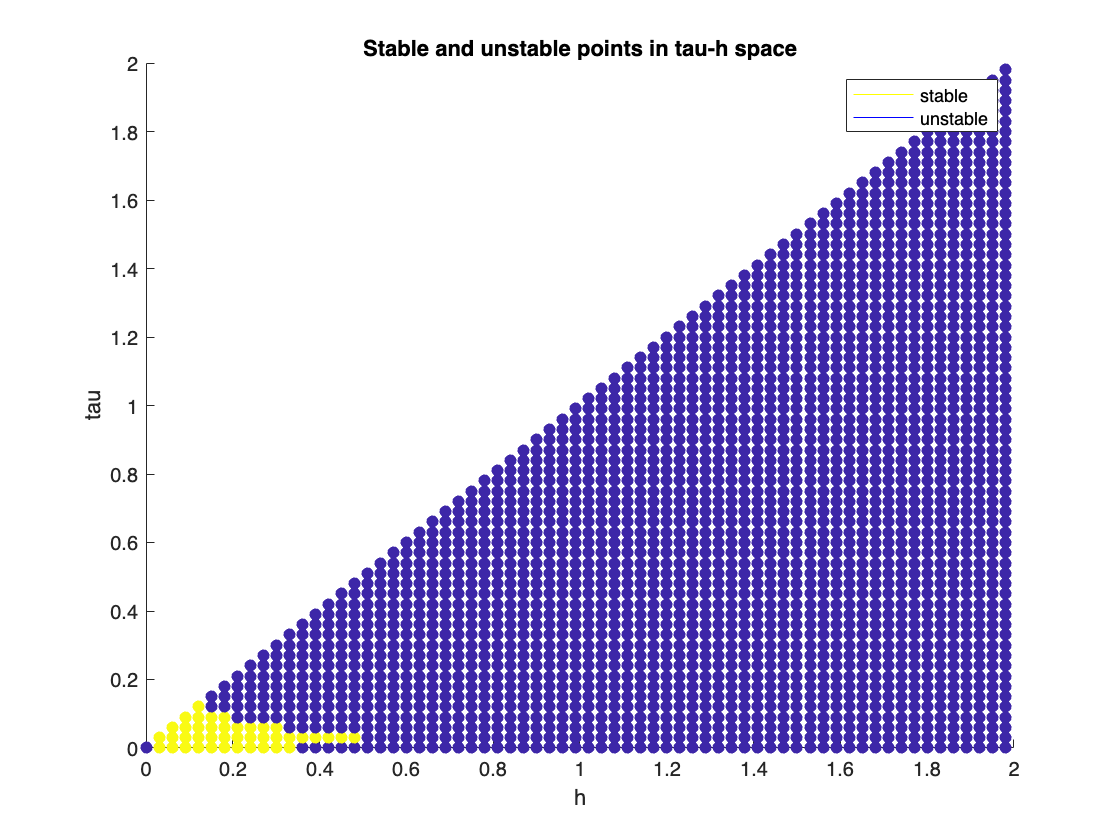

a = 5;
b = 3;
c = 1;
A = [a-b, 0.5-c; 0, 1];
B = [0; 1];
p2 = [-1, -2];
K2 = place(A, B, p2);

% create grid of tau and h values
tau_values = 0:0.03:2;
h_values = 0:0.03:2;

% preallocate arrays for x, y, and color values
x = [];
y = [];
colors = [];

for i = 1:length(tau_values)
    h = h_values(i);
    tau_values_i = 0:0.03:h;
    for j = 1:length(tau_values_i)
        tau = tau_values_i(j);
        
        % compute closed-loop system matrix
        Fx = expm(A*h);
        Fu = (expm(A*h) - expm(A*(h-tau)))/A * B;
        G1 = (expm(A*(h-tau)) - eye(size(A)))/A * B;
        Fe = [Fx, Fu; zeros(1,2) zeros(1)]; 
        Ge = [G1; 1];
        Ke2 = [K2 0];
        Acl1de2 = Fe - Ge * Ke2;
        % check stability of closed-loop system
        eigvals2 = eig(Acl1de2);
        if all(abs(eigvals2) < 1)
            % point is stable, add to x, y, and color arrays
            x = [x h];
            y = [y tau];
            colors = [colors 1]; 
        else
            % point is unstable, add to x, y, and color arrays
            x = [x h];
            y = [y tau];
            colors = [colors 0]; % use NaN for invisible
        end
    end
end

% plot scatter
figure;
scatter(x, y, [], colors, 'filled');
xlim([0 2]);
ylim([0 2]);
xlabel('h');
ylabel('tau');
title('Stable and unstable points in tau-h space');
hold on
L(1) = plot(nan, nan, 'y');
L(2) = plot(nan, nan, 'b');
legend(L,{'stable', 'unstable'})